clear; clc; close all;

%% -------------------- User Inputs ---------------------------------------
Pc   = 7e6;          % chamber pressure [Pa] (e.g., 70 bar)
Tc   = 3400;         % chamber temperature [K]
gamma= 1.22;         % specific heat ratio (typical LOX/RP-1 ballpark 1.2–1.3)
R    = 355;          % gas constant [J/(kg·K)] (example exhaust gas)
At   = 0.003;        % throat area [m^2]
eps_list = [5 10 20 40];   % expansion ratios to compare (Ae/At)

h_km = linspace(0,30,200); % altitude [km] sweep
Pa_vec = std_atm_pressure(h_km*1000); % ambient pressure [Pa]

%% -------------------- Precompute throat mass flow -----------------------
mdot = choked_mass_flow(Pc,Tc,gamma,R,At);   % [kg/s]
fprintf('Choked mass flow: %.3f kg/s\n', mdot);

Choked mass flow: 12.470 kg/s



colors = lines(numel(eps_list));
thrust_mat = zeros(numel(eps_list), numel(Pa_vec));

for k = 1:numel(eps_list)
    eps = eps_list(k);
    % Exit Mach from area ratio:
    Me  = mach_from_area_ratio(eps,gamma);
    % Exit static properties (isentropic):
    Te  = Tc / (1 + (gamma-1)/2 * Me^2);
    pe_ratio = (1 + (gamma-1)/2 * Me^2)^(-gamma/(gamma-1));
    Pe  = Pc * pe_ratio;
    Ae  = eps * At;
    Ve  = Me * sqrt(gamma*R*Te);

    % Thrust vs. altitude (varying Pa)
    Fe = mdot*Ve + (Pe - Pa_vec).*Ae;
    thrust_mat(k,:) = Fe;

    % Print a quick line for sea level:
    [~,i0] = min(abs(h_km-0));
    fprintf('eps=%g: Ve=%.1f m/s, Pe=%.1f kPa, F_SL=%.0f N\n', ...
        eps, Ve, Pe/1e3, Fe(i0));
end

eps=5: Ve=2499.9 m/s, Pe=214.0 kPa, F_SL=32864 N
eps=10: Ve=2714.6 m/s, Pe=83.1 kPa, F_SL=33304 N
eps=20: Ve=2878.6 m/s, Pe=33.2 kPa, F_SL=31809 N
eps=40: Ve=3008.3 m/s, Pe=13.5 kPa, F_SL=26976 N


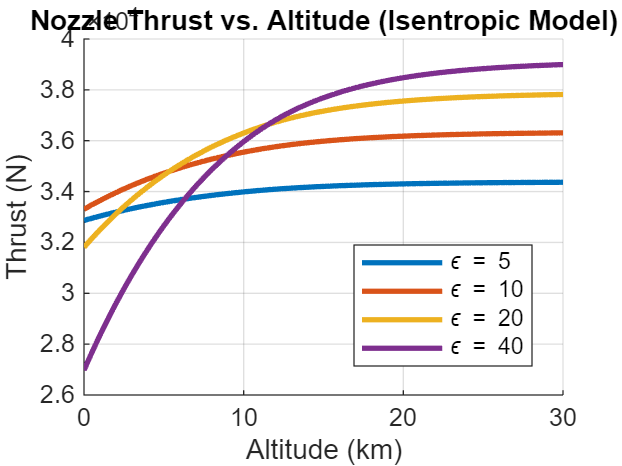


%% -------------------- Plot ------------------------------------------------
figure('Color','w'); hold on; grid on;
for k = 1:numel(eps_list)
    plot(h_km, thrust_mat(k,:), 'LineWidth',2, 'DisplayName',sprintf('\\epsilon = %g', eps_list(k)));
end
xlabel('Altitude (km)');
ylabel('Thrust (N)');
title('Nozzle Thrust vs. Altitude (Isentropic Model)');
legend('Location','best');


%% -------------------- Helper Functions -----------------------------------
function mdot = choked_mass_flow(Pc,Tc,gamma,R,At)
    % Choked mass flow at throat (Me = 1)
    coeff = sqrt(gamma/R)* ( (2/(gamma+1))^((gamma+1)/(2*(gamma-1))) );
    mdot = Pc*At/Tc^0.5 * coeff;
end

function Me = mach_from_area_ratio(eps,gamma)
    % Solve A/A* = eps for supersonic Me (Newton loop)
    f = @(M) 1./M .* ( (2/(gamma+1)*(1+(gamma-1)/2*M.^2)) .^ ((gamma+1)/(2*(gamma-1))) ) - eps;
    % Good initial guess grows with eps:
    M = max(2, 0.5*eps); 
    for it=1:50
        % Derivative via small finite diff
        h = 1e-6*max(1,M);
        df = (f(M+h)-f(M-h))/(2*h);
        Mnew = M - f(M)/df;
        if abs(Mnew-M) < 1e-10, M = Mnew; break; end
        M = max(1.01,Mnew); % keep supersonic
    end
    Me = M;
end

function Pa = std_atm_pressure(h)
    % International Standard Atmosphere up to 32 km (piecewise lapse)
    % Inputs: h [m], Outputs: Pa [Pa]
    Pa = zeros(size(h));
    for i=1:numel(h)
        z = h(i);
        if z <= 11000
            T0=288.15; p0=101325; a=-0.0065; g0=9.80665; R=287.05287;
            T = T0 + a*z; Pa(i) = p0*(T/T0)^(-g0/(a*R));
        elseif z <= 20000
            % isothermal 11–20 km
            T11=216.65; p11=22632.06; g0=9.80665; R=287.05287;
            Pa(i) = p11*exp(-g0*(z-11000)/(R*T11));
        else
            % 20–32 km linear lapse
            T20=216.65; p20=5474.889; a=0.001; g0=9.80665; R=287.05287;
            T = T20 + a*(z-20000); Pa(i) = p20*(T/T20)^(-g0/(a*R));
        end
    end
end
